# Homework 8  - Farshad Bolouri - R11630884

### Problem 1) 

clear
close all
load test_signal.mat
Fs= 500;
N = length(test_signal);
duration = 5;

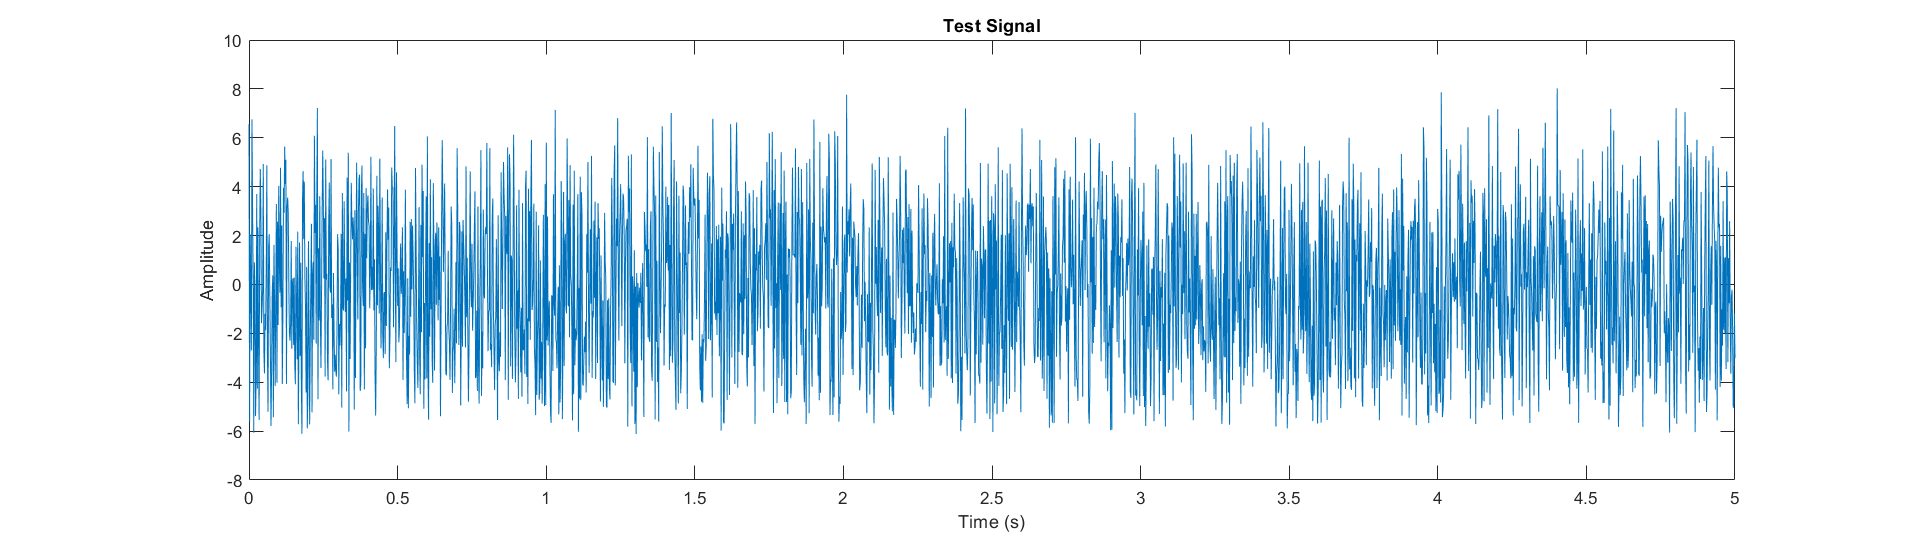

time = linspace(0, duration, N);
graph = figure;
plot(time, test_signal)
title('Test Signal')
xlabel('Time (s)')
ylabel('Amplitude')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

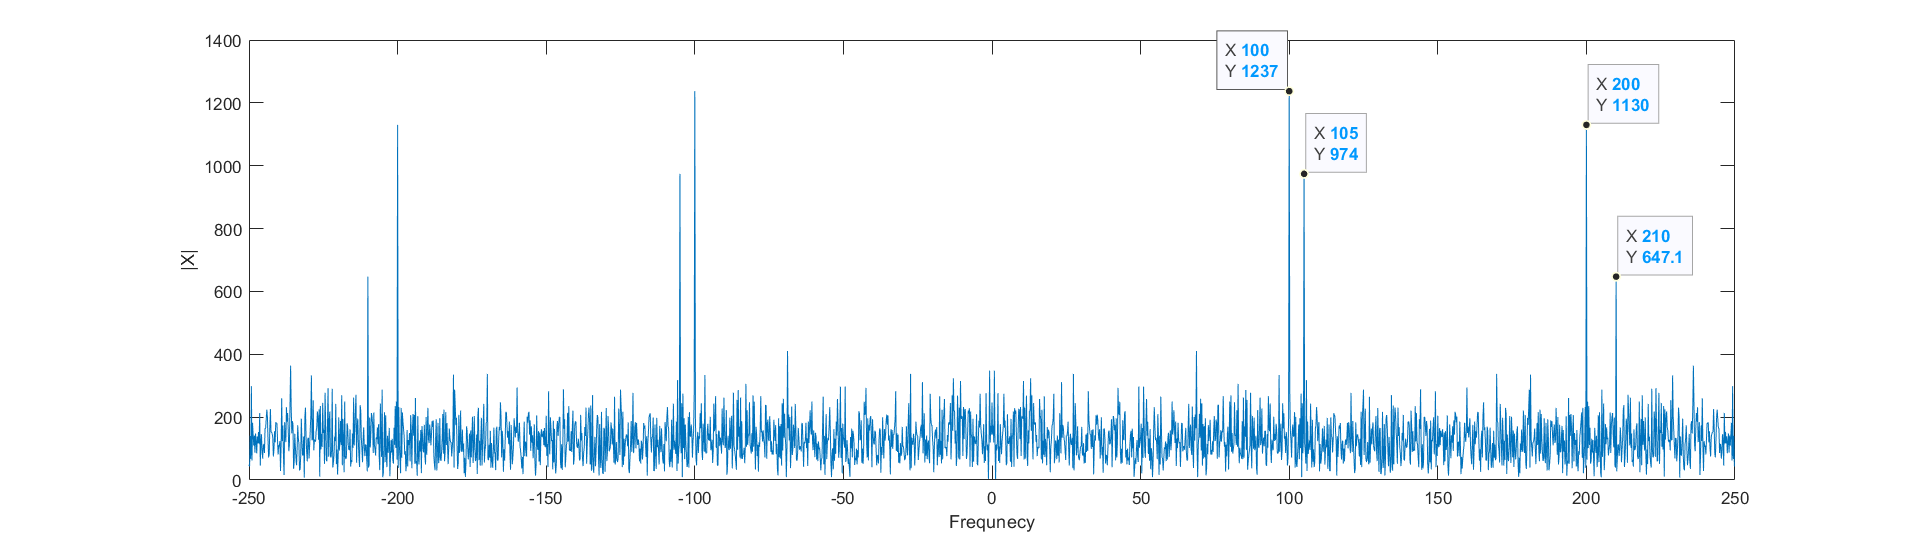

FT = fft(test_signal,2500);

spectrum = abs(fftshift(FT));                  % Zero-Centered FFT
spectrumF = (-N/2:N/2-1)...
    /N*Fs;                   % Zero-Centered Frequency Range

graph = figure;
plot(spectrumF, spectrum)
xlabel('Frequnecy')
ylabel('|X|')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

ax = gca;
chart = ax.Children(1);
datatip(chart,105,974);
datatip(chart,210,647.1);
datatip(chart,200,1130);
datatip(chart,100,1237, 'Location', 'northwest');

*This signal seems to consist of 4 different sinusoids with added noise. The frequencies of the sinusoids are 100Hz , 105Hz, 200Hz, and 210Hz.*

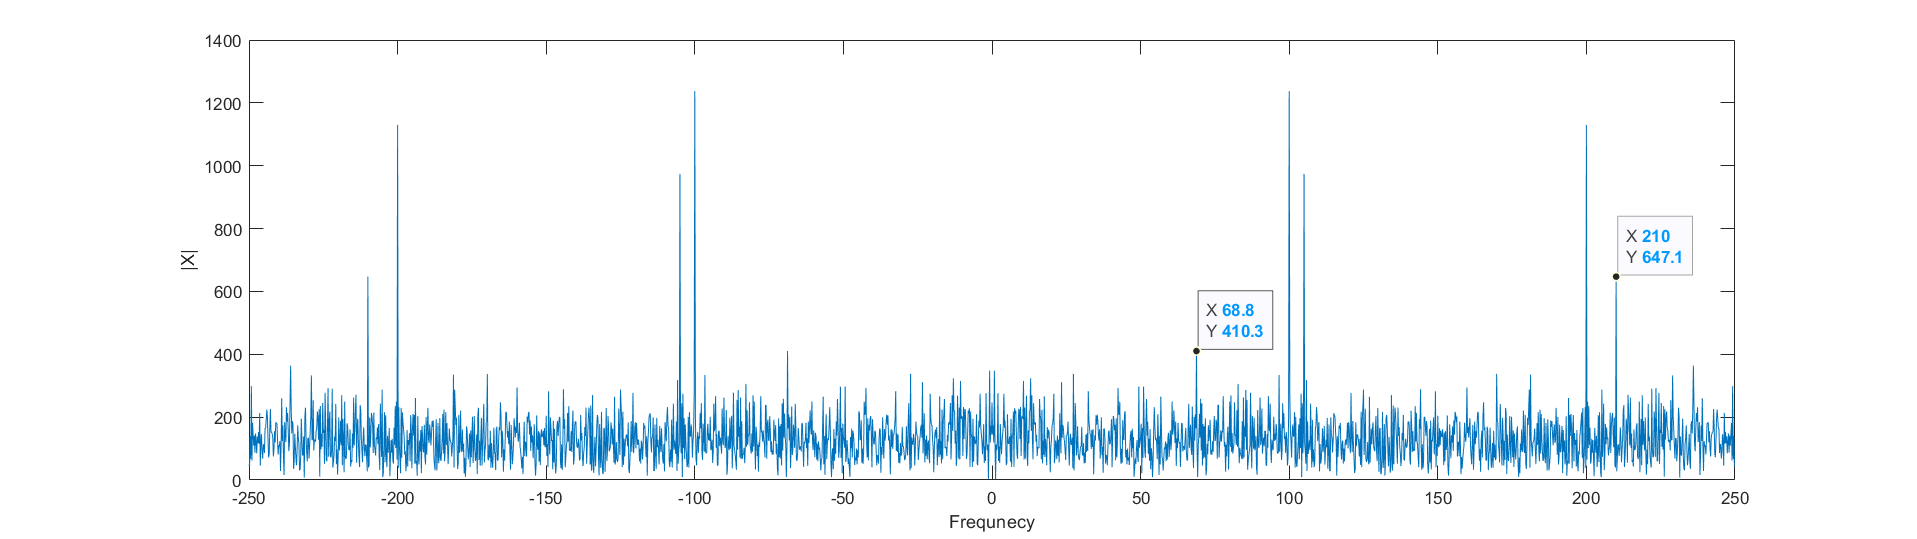

graph = figure;
plot(spectrumF, spectrum)
xlabel('Frequnecy')
ylabel('|X|')
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
chart = ax.Children(1);
datatip(chart,210,647.1);
datatip(chart, 68.8, 410.3);

*To confirm the points shown in the graph to be the lowest of the four signal frequencies, and the highest of the noise components we can do the following:*

maxAmplitudes= maxk(spectrum(N/2:N), 5);
lowestSinusoidA = maxAmplitudes(4)

lowestSinusoidA = 647.0538

highestNoiseA = maxAmplitudes(5)

highestNoiseA = 410.3063

*This shows that we were indeed correct. Now we'll calculate the SNR in dBs:*

SNR = pow2db(lowestSinusoidA) - pow2db(highestNoiseA)

SNR = 1.9783

P = nextpow2(N)

P = 12

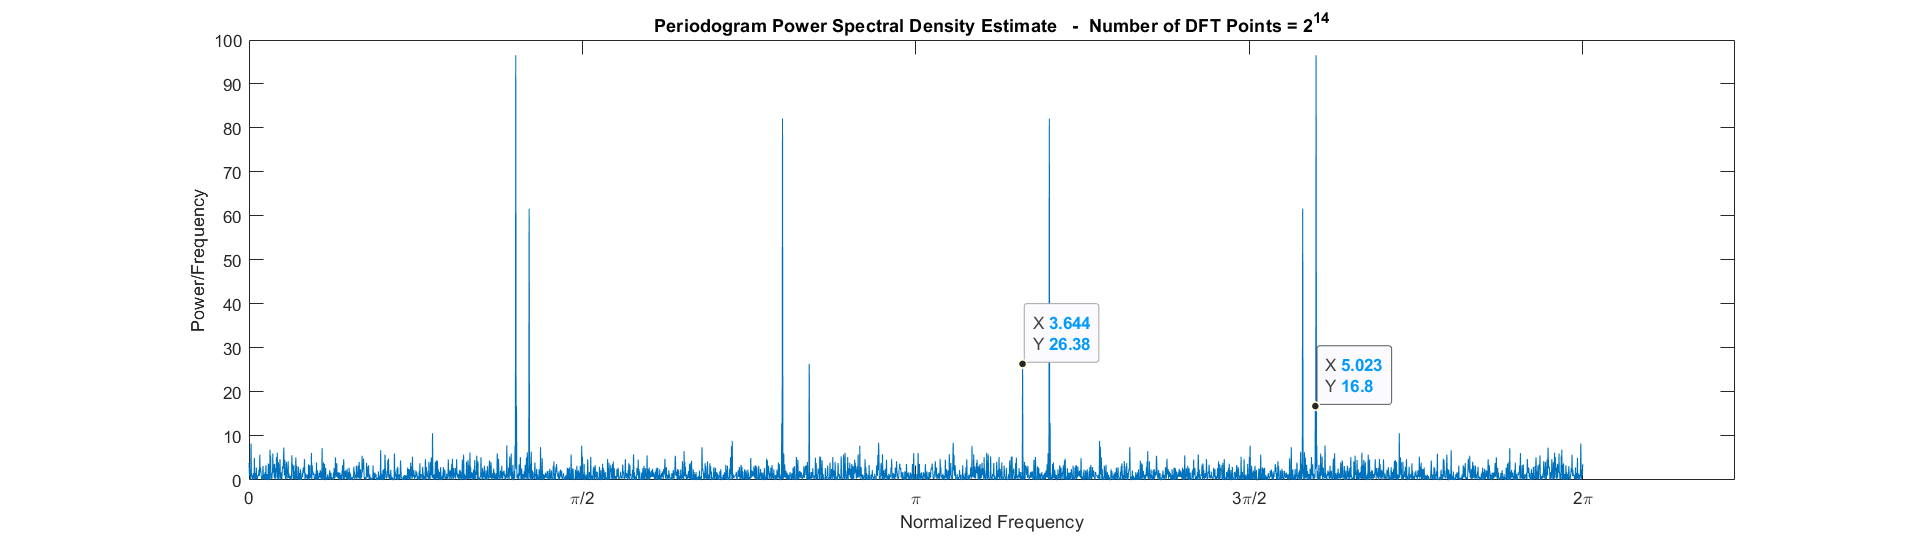

graph = figure;
[pxx14, w14] = periodogram(test_signal, [], 2^(P+2),'twosided','psd');     % Window Type: rectangular window
plot(w14, pxx14)
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{14}')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
ax = gca;
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
chart = ax.Children(1);
datatip(chart,3.644,26.38);
datatip(chart, 'DataIndex', 13099);

SNR14 = pow2db(26.38) - pow2db(16.8)

SNR14 = 1.9597

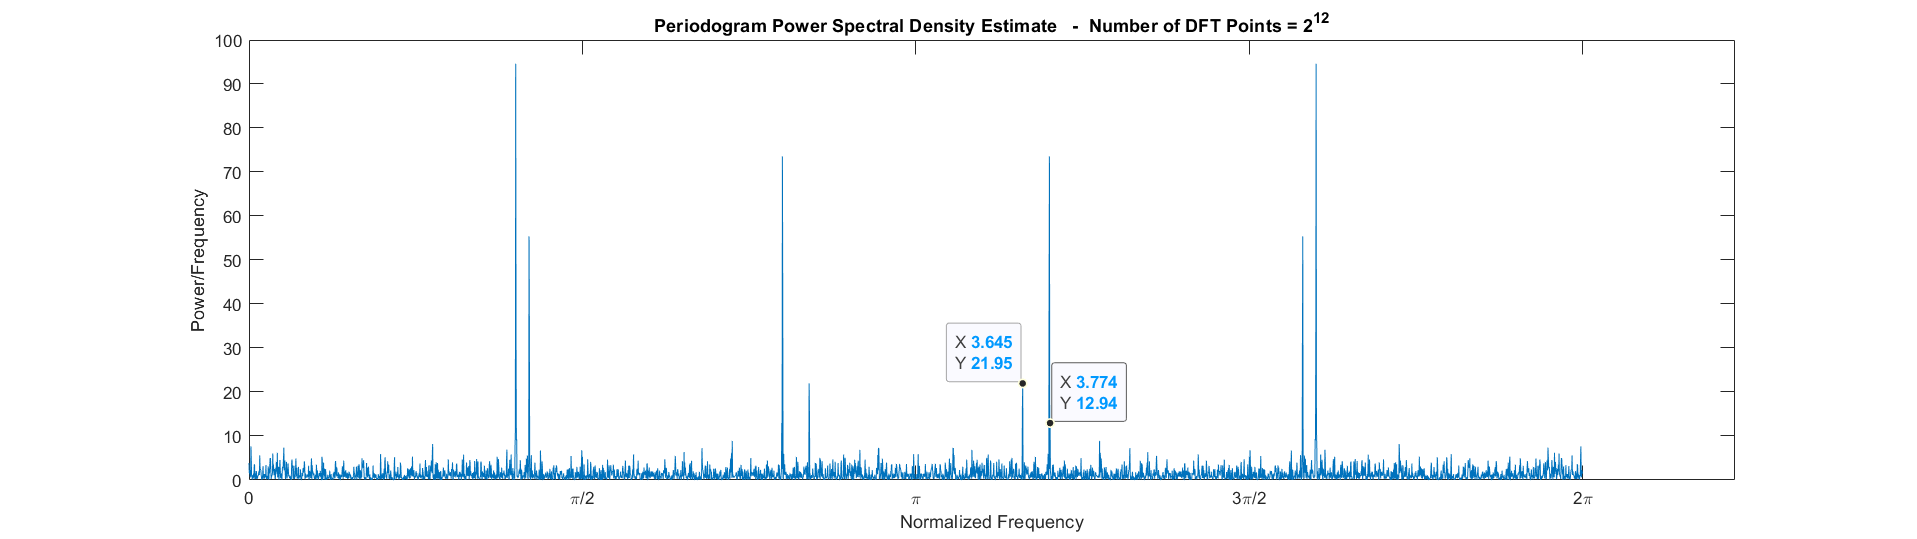

graph = figure;
[pxx12, w12] = periodogram(test_signal, [], 2^P,'twosided','psd');     % Window Type: rectangular window
plot(w12, pxx12)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{12}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
ax = gca;
chart = ax.Children(1);
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 2461);

SNR12 = pow2db(21.95) - pow2db(12.94)

SNR12 = 2.2950

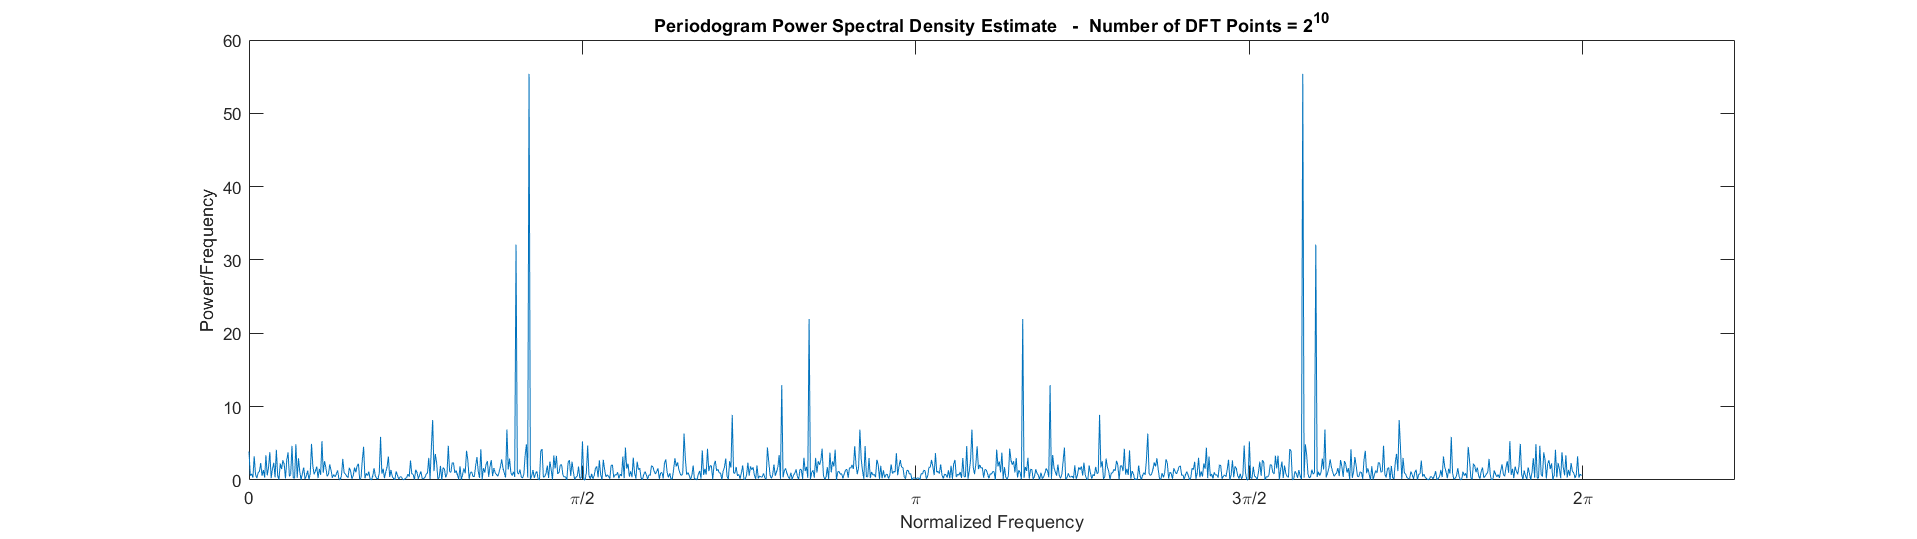

graph = figure;
[pxx10, w10] = periodogram(test_signal, [], 2^(P-2),'twosided','psd');     % Window Type: rectangular window
plot(w10, pxx10)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{10}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})

*If you compare this plot to the last 2 plots you can see that we are actually missing one of our 4 frequencies. Let's compare them once more:*

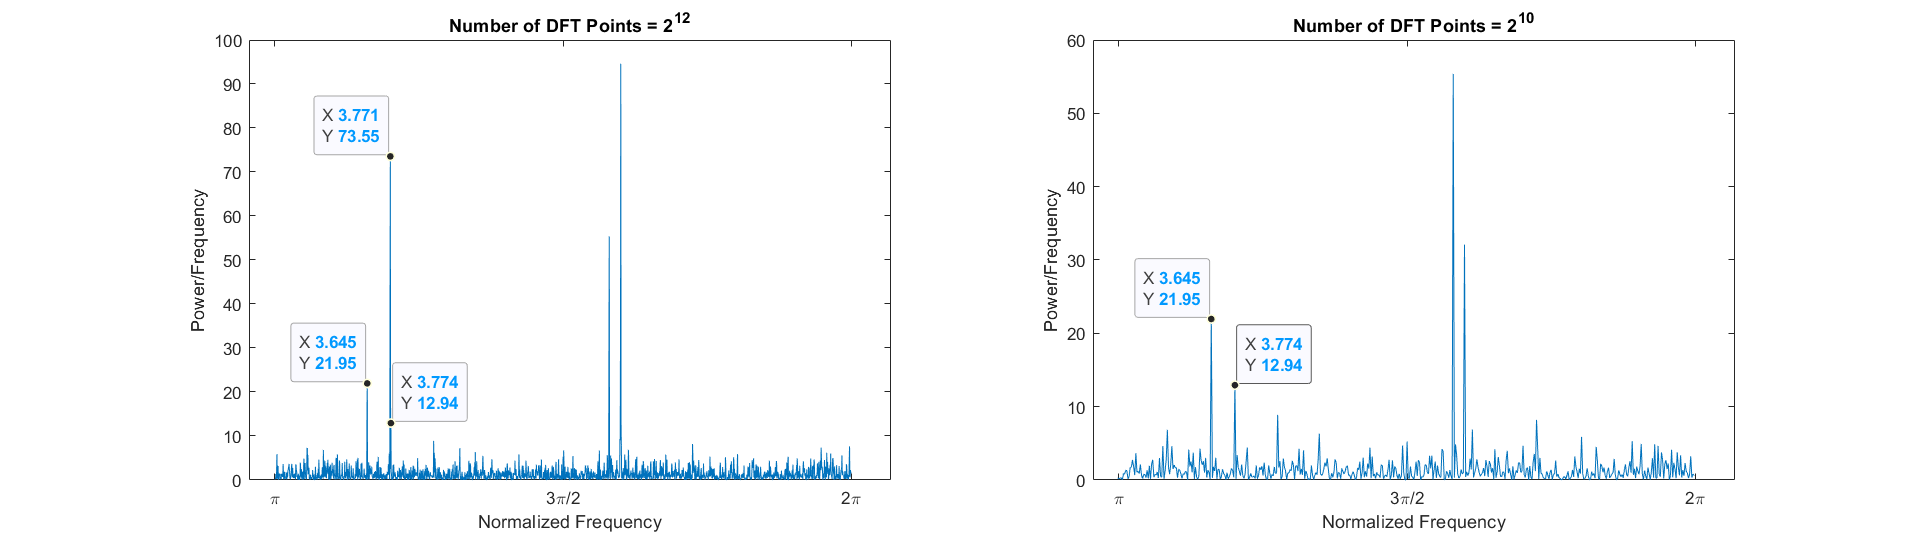

graph = figure;
subplot(1,2,1)
plot(w12(length(pxx12)/2:end), pxx12(length(pxx12)/2:end))
title('Number of DFT Points = 2^{12}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
ax = gca;
chart = ax.Children(1);
set(gca,'XTick',pi:pi/2:2*pi) 
set(gca,'XTickLabel',{'\pi','3\pi/2','2\pi'})
datatip(chart,3.771, 73.55, 'Location', 'northwest');
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 414);
subplot(1,2,2)
plot(w10(length(pxx10)/2:end), pxx10(length(pxx10)/2:end))
title('Number of DFT Points = 2^{10}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
ax = gca;
chart = ax.Children(1);
set(gca,'XTick',pi:pi/2:2*pi) 
set(gca,'XTickLabel',{'\pi','3\pi/2','2\pi'})
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 'DataIndex' , 105);

*Therefore we know we cannot use P = 10 for this task. Let's try 11:*

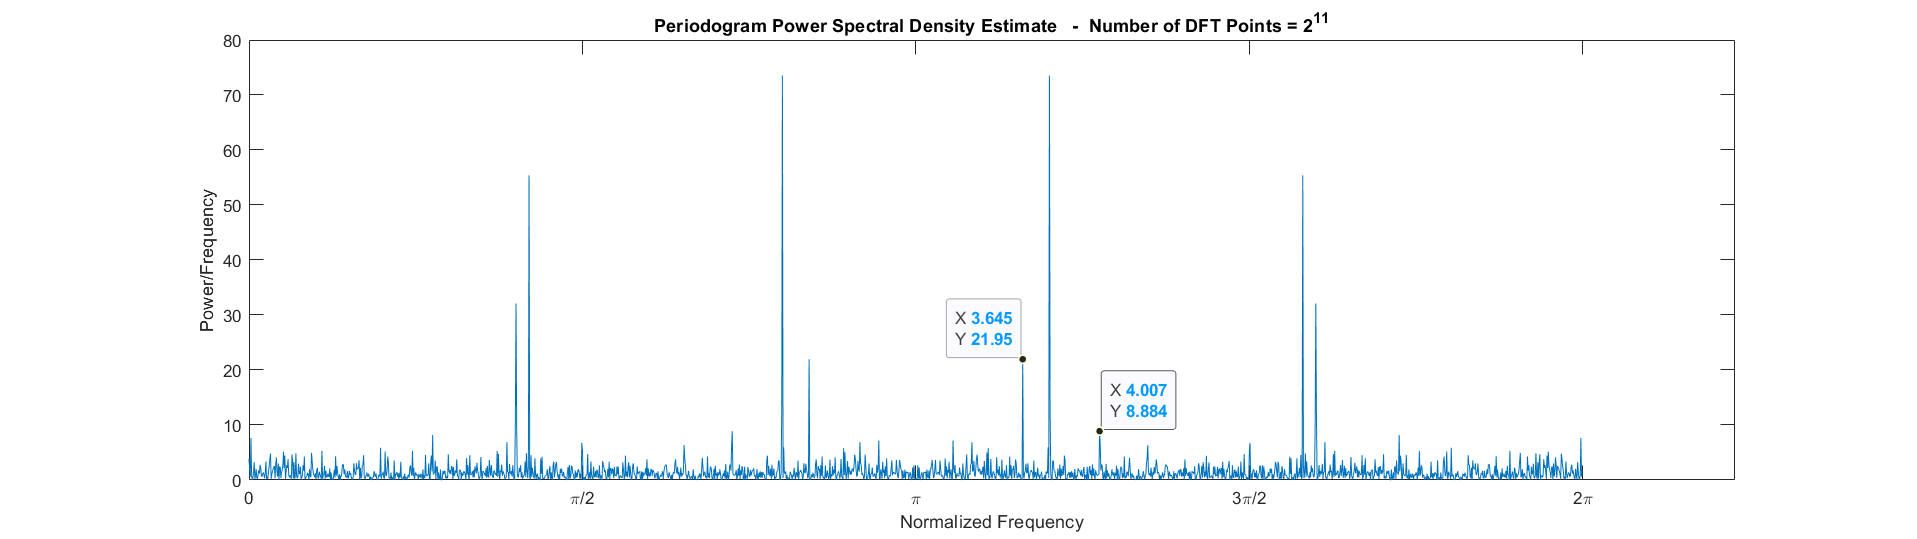

graph = figure;
[pxx11, w11] = periodogram(test_signal, [] , 2^(P - 1),'twosided','psd');     % Window Type: rectangular window
plot(w11, pxx11)
title('Periodogram Power Spectral Density Estimate   -  Number of DFT Points = 2^{11}')
xlabel('Normalized Frequency')
ylabel('Power/Frequency')
set(graph,'Units','normalized','Position',[0 0 1 0.5]); 
ax = gca;
chart = ax.Children(1);
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
datatip(chart,3.645, 21.95, 'Location', 'northwest');
datatip(chart, 4.007 , 8.884);

*With P = 11 we seem to be still able to see the four frequencies!*

SNR11 = pow2db(21.95) - pow2db(8.884)

SNR11 = 3.9283

* I started with first finding P in a way that satifies the equation *$2^P \ge \textrm{length}\;\textrm{of}\;\textrm{the}\;\textrm{test}\;\textrm{signal}$, *in which P = 12.*

*You can see how the behavior of the periodogram changes as we reduce P. As we use the less number of DFT points we are also plotting smaller number of points (calculating FFTs with less points); which results to getting less details in our periodogram (which can result to losing the differentiating factor between the sinusoid frequencies and the noise frequencies). Note that as P is reducing the amplitude of our 4 frequencies are decreasing and eventually disappearing.*

*After trying out the different different nfft's (all powers of 2) as shown above, I found *$2^{11}$* to be the smallest numbers of DFT points we could use while still being able to identify the 4 sinusoid frrequencies.  *$2^{11}$ *also produces the highest SNR as shown above!*

*I also tried different window types and found the rectangular window to be the best for this signal.*